clear all
omegai = [0,0,0,0,0,0,0]

omegai =      0     0     0     0     0     0     0


si = [0,0.2,0.4,0.6,0.6,1,1]

si =          0    0.2000    0.4000    0.6000    0.6000    1.0000    1.0000



omegai = zeros(length(si),1)

omegai =      0
     0
     0
     0
     0
     0
     0


tau = 1

tau = 1

deltav = 0.2

deltav = 0.2000

L2 = 3000

L2 = 3000

Na = 20000

Na = 20000

Mv = 20

Mv = 20

enable_constraints=1;


[C, M, number_of_elements] = define_grid(omegai,si,tau,deltav,L2,Na,Mv,enable_constraints)

C = 1×7 cell array
    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}


M = 1×7 cell array
    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}    {1×120 cell}


number_of_elements = 120

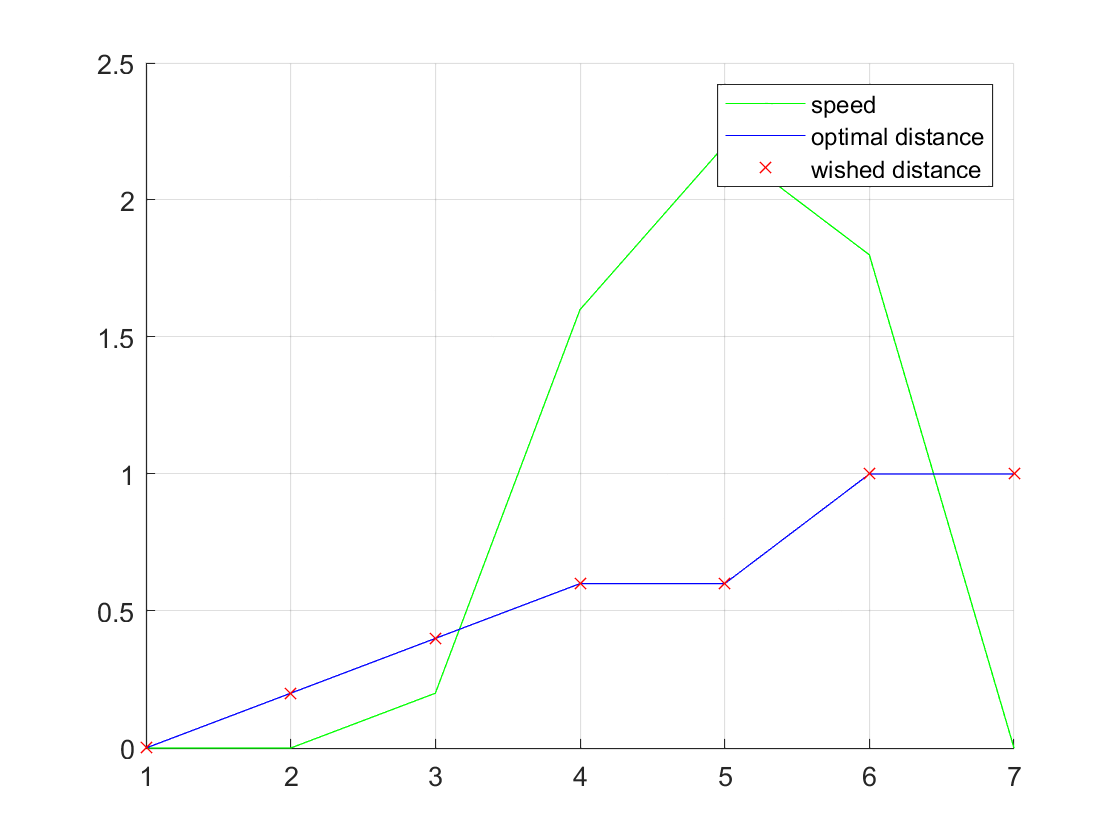


% terminal cost
Jh = zeros(1,number_of_elements);
[u,J] = dptv( M, C, Jh);
[u_one,J_one] = showOneOptimalWay(u,J);
[v_one,s_one] = decodev_s(si,tau,deltav,Mv,u_one);
figure()
hold on
plot(v_one,"g")
plot(s_one,"b-")
plot(si,"rx")
grid on;
hold off
legend("speed","optimal distance","wished distance")

function [u,J] = dptv( M, C, T)
h = length(M);
for l = 1:length(T)
    J_{h+1}{l} = T(l);
end
for k = h:-1:1
    ni = length(M{k}); % state dimension
    for i=1:ni
        nj = length(M{k}{i});
        caux = zeros(1,nj);
        for j = 1:nj
            caux(j) = C{k}{i}{j} + J_{k+1}{M{k}{i}{j}};
        end
        [a,b] = sort(caux);
        J_{k}{i} = a(1); J{k}{i} = J_{k}{i};
        u{k}{i}(1) = b(1);
        for ell = 2:length(a)
            if abs( a(ell) - a(1))<1e-8
                u{k}{i}(ell) = b(ell);
            else
                break;
            end
        end
    end
end

end


